# Circular scattered field: incident, total and scattered fields

This example computes, on the **same mesh**, the field without and with the target, and the scattered field caused by the target:

- incident field $E_{inc}$: DOI without target (`incident`),

- total field $E_{tot}$: DOI with the target (`total`),

- scattered field $E_{sc} = E_{tot} - E_{inc}$.

For the imaging example (`main``_i``maging_born_tsvd.mlx`) a third simulation is saved: the incident field on a different, coarser **reconstruction mesh** (`operator`). It plays the role of the *model* of the measurement system, while `total` plays the role of the measurement. Using different meshes avoids the *inverse crime*.

Units are SI (m, Hz, S/m) and the time convention is $e^{+j\omega t}$.

## Setup

clc; close all; clear;
here = fileparts(mfilename('fullpath'));                       % folder of this example
if ~isfolder(fullfile(here, '..', '..', 'Forward_solvers'))      % Live Editor: use the open file
    try, here = fileparts(matlab.desktop.editor.getActiveFilename); catch, here = pwd; end
end
addpath(fullfile(here, '..', '..'));
setup_osmi;
resultsDir = fullfile(here, 'results');

## Frequency

sim.f = 1e9;                                   % Hz

## Materials


$$\varepsilon_c = \varepsilon' - j\,\frac{\sigma}{\omega\,\varepsilon_0}$$


materials.background.epsr  = 10;
materials.background.sigma = 0.02;             % S/m

materials.doi.epsr  = 10;
materials.doi.sigma = 0.02;

materials.target.epsr  = 45;
materials.target.sigma = 0.06;

## Geometry

geom.doiRadius    = 0.10;
geom.antennaRing  = 0.12;
geom.nAntennas    = 12;
geom.targetRadius = 0.01;
geom.targetCenter = [0.03, 0.03];

## Mesh control


$$\lambda = \frac{c_0}{f\sqrt{\varepsilon'}}$$


- data mesh (incident and total fields): $h = \lambda/30$ in the DOI, target and antennas, $\lambda/24$ in the background,

- reconstruction mesh (imaging operator): $h = \lambda/24$ in the DOI and target.

c0         = 299792458;
lambda_doi = c0/(sim.f*sqrt(materials.doi.epsr));
lambda_bg  = c0/(sim.f*sqrt(materials.background.epsr));
lambda_tgt = c0/(sim.f*sqrt(materials.target.epsr));

meshData.hDOI    = lambda_doi/30;
meshData.hBG     = lambda_bg/24;
meshData.hAnt    = lambda_bg/30;
meshData.hTarget = lambda_tgt/30;
meshData.rAnt    = meshData.hAnt;

meshRec         = meshData;
meshRec.hDOI    = lambda_doi/24;
meshRec.hTarget = lambda_tgt/24;

## Incident field (no target)

The target region is filled with the DOI medium (`includeTarget = false`), so the mesh is identical to the one of the total field.

opts.outputDir     = resultsDir;
opts.current       = 1e-3;                     % A
opts.name          = "incident";
opts.includeTarget = false;
incident = generate_fields(sim, materials, geom, meshData, opts);

[incident] geometry radius 0.123 m -> square 0.493 m, PML from 0.185 m (0.062 m thick, gap 0.062 m)
[incident] mesh: 17790 nodes, 35174 triangles; solving 12 sources ...
Saved "incident"  ->  C:\Users\nicky\OneDrive\Desktop\Tomo_Hackathon\Hackathon\Hackathon\Examples\Circular_scattered_field\results\incident.mat


## Total field (with target)

opts.name          = "total";
opts.includeTarget = true;
[total, scenario] = generate_fields(sim, materials, geom, meshData, opts);

[total] geometry radius 0.123 m -> square 0.493 m, PML from 0.185 m (0.062 m thick, gap 0.062 m)
[total] mesh: 17790 nodes, 35174 triangles; solving 12 sources ...
Saved "total"  ->  C:\Users\nicky\OneDrive\Desktop\Tomo_Hackathon\Hackathon\Hackathon\Examples\Circular_scattered_field\results\total.mat


## Imaging operator (no target, reconstruction mesh)

opts.name          = "operator";
opts.includeTarget = false;
operator = generate_fields(sim, materials, geom, meshRec, opts);

[operator] geometry radius 0.123 m -> square 0.493 m, PML from 0.185 m (0.062 m thick, gap 0.062 m)
[operator] mesh: 16221 nodes, 32036 triangles; solving 12 sources ...
Saved "operator"  ->  C:\Users\nicky\OneDrive\Desktop\Tomo_Hackathon\Hackathon\Hackathon\Examples\Circular_scattered_field\results\operator.mat


## Geometry and mesh

The dashed red square marks the start of the PML.

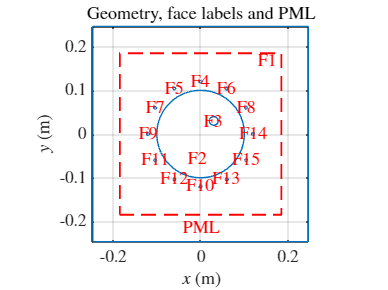

plotGeometry(scenario);

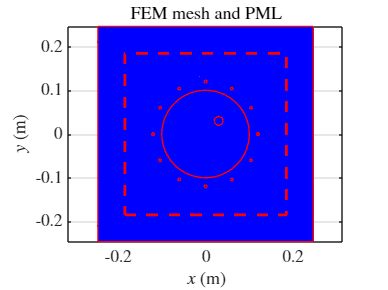

plotMesh(scenario);

## Contrast

The scattered field is caused by the contrast between the two scenarios,


$$\Delta\varepsilon_r = \varepsilon_{r,\,total} - \varepsilon_{r,\,incident}$$


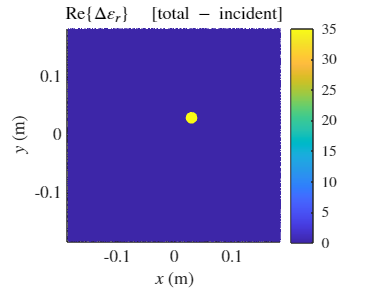

plotPermittivity(total, 'real', 'Reference', incident);

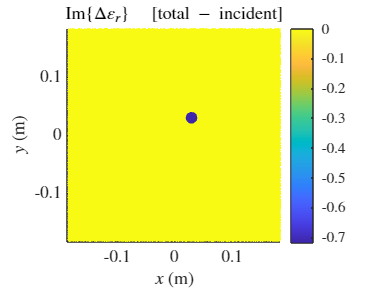

plotPermittivity(total, 'imag', 'Reference', incident);

## Incident, total and scattered fields

Choose the transmitter `tx`. The scattered field is plotted as the difference of the two simulations (`'Reference', incident`).

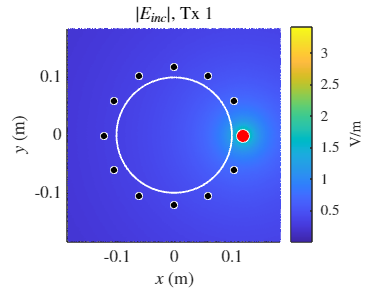

tx = 1;

plotField(incident, tx, 'abs', 'Title', "$|E_{inc}|$, Tx " + tx);

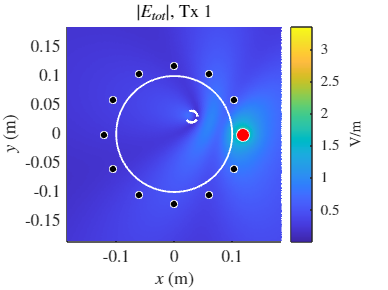

plotField(total,    tx, 'abs', 'Title', "$|E_{tot}|$, Tx " + tx);

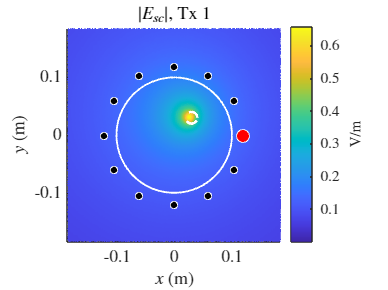

plotField(total,    tx, 'abs', 'Reference', incident, 'Title', "$|E_{sc}|$, Tx " + tx);

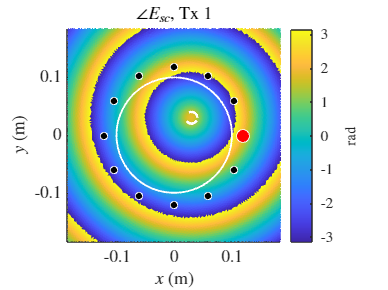

plotField(total,    tx, 'phase', 'Reference', incident, 'Title', "$\angle E_{sc}$, Tx " + tx);

## Scattered field at the antennas

The data used for imaging: $E_{sc}(m,n)$, receiver $m$, transmitter $n$.

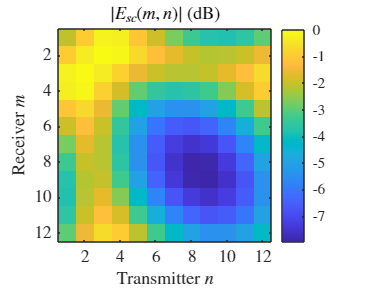

E_sc = total.Eprobes - incident.Eprobes;
figure;
imagesc(20*log10(abs(E_sc)/max(abs(E_sc(:)))));
axis image; colorbar;
xlabel('Transmitter $n$'); ylabel('Receiver $m$');
title('$|E_{sc}(m,n)|$ (dB)');

## Interactive viewer

Field: `total`, `incident` or their difference (scattered field). Colour limits are automatic; untick *Auto* in the window to type your own *Min* / *Max*.

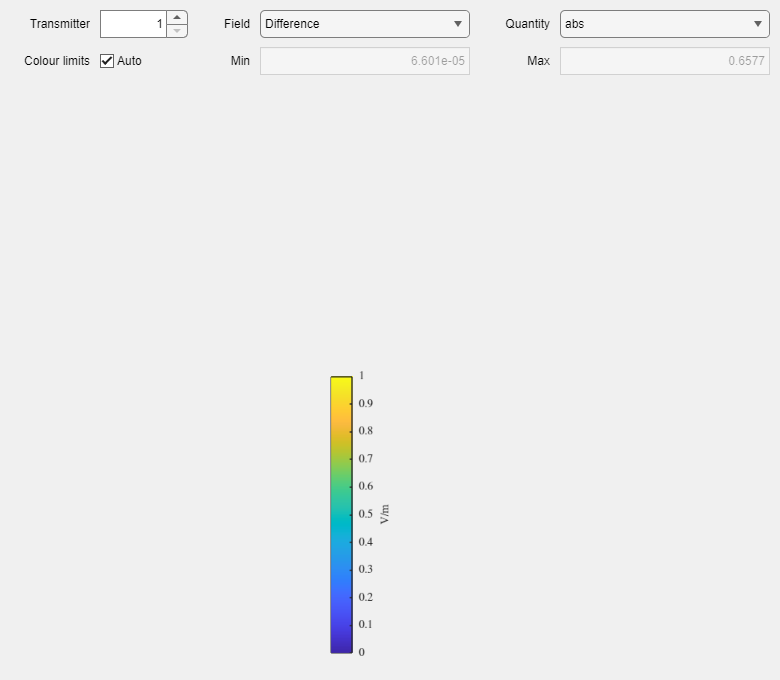

fieldViewer(total, incident);